## **Assignment** 4

## Group** F**

- 0473086 **Chinnawat Danakkaew **(c.danakkaew@campus.tu-berlin.de)

- 0468041 **Muhammet Gündogdu **(Muhammet.gun94@campus.tu-berlin.de)

- 0474419** Ayomide Oluyemi Olabode **(olabode@campus.tu-berlin.de)

- 0473604 **Partist Poopat **(partist.poopat@campus.tu-berlin.de)

- 0461758 **Enoch Kwabena Asare** (asare@campus.tu-berlin.de)

**1.**

clc
clear
% vernaleqinox
alpha = 0; delta = 0;
vernaleqinox = [delta,alpha,1];
xi0 = latlonr2xyz(vernaleqinox)  %(rad,rad,m)-->(m,m,m)

xi0 =      1     0     0


% JD in 1990-2030
yyyy = 1990:2030;
mm=1; dd=1; ut1=12; minute=0; second=0;
jd = gre2jd(yyyy,mm,dd,ut1,minute,second);
jd = jd(1:41) % Extract only Julian Date

jd =      2447893     2448258     2448623     2448989     2449354     2449719     2450084     2450450     2450815     2451180     2451545     2451911     2452276     2452641     2453006     2453372     2453737     2454102     2454467     2454833     2455198     2455563     2455928     2456294     2456659     2457024     2457389     2457755     2458120     2458485     2458850     2459216     2459581     2459946     2460311     2460677     2461042     2461407     2461772     2462138     2462503


% P(JD)
%xip = 
for i = 1:length(jd)
    Pjd = prec(jd(i)); 
    xip = Pjd * xi0';
    % (m,m,m) --> (rad,rad,m)
    sph_ip = xyz2latlonr(xip); 
    % [delta,alpha,1] - [rad,rad,m]
    
    delta2(i) = sph_ip(1)*180/pi; % degree
    alpha2(i) = sph_ip(2)*12/pi; % hour angle
end
delta2,alpha2,yyyy

delta2 =    -0.0557   -0.0501   -0.0445   -0.0390   -0.0334   -0.0278   -0.0223   -0.0167   -0.0111   -0.0056         0    0.0056    0.0111    0.0167    0.0223    0.0278    0.0334    0.0390    0.0445    0.0501    0.0557    0.0612    0.0668    0.0724    0.0780    0.0835    0.0891    0.0947    0.1002    0.1058    0.1113    0.1169    0.1225    0.1281    0.1336    0.1392    0.1448    0.1503    0.1559    0.1615    0.1670


alpha2 =    -0.0085   -0.0077   -0.0068   -0.0060   -0.0051   -0.0043   -0.0034   -0.0026   -0.0017   -0.0009         0    0.0009    0.0017    0.0026    0.0034    0.0043    0.0051    0.0060    0.0068    0.0077    0.0085    0.0094    0.0103    0.0111    0.0120    0.0128    0.0137    0.0145    0.0154    0.0162    0.0171    0.0179    0.0188    0.0196    0.0205    0.0214    0.0222    0.0231    0.0239    0.0248    0.0256


yyyy =         1990        1991        1992        1993        1994        1995        1996        1997        1998        1999        2000        2001        2002        2003        2004        2005        2006        2007        2008        2009        2010        2011        2012        2013        2014        2015        2016        2017        2018        2019        2020        2021        2022        2023        2024        2025        2026        2027        2028        2029        2030


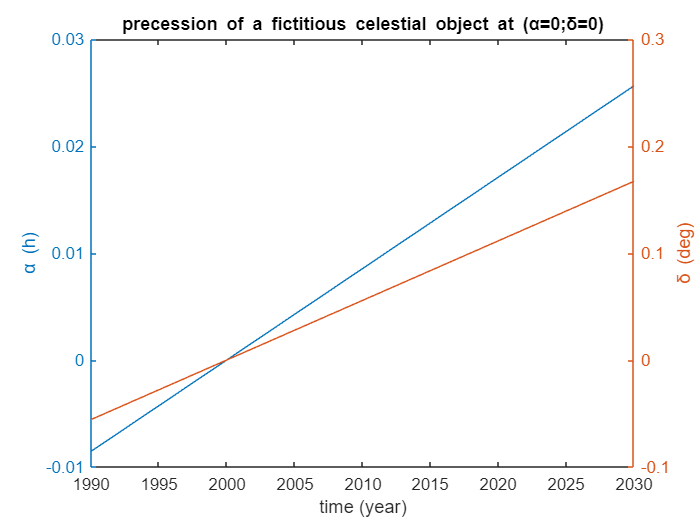

fig1 = plotyy(yyyy,alpha2,yyyy,delta2);
title('precession of a fictitious celestial object at (\alpha=0;\delta=0)')
xlabel('time (year)')
ylabel(fig1(1),'\alpha (h)')
ylabel(fig1(2),'\delta (deg)')

**2.**

clc
clear
% vernaleqinox
alpha = 0; delta = 0;
vernaleqinox = [delta,alpha,1];
xi0 = latlonr2xyz(vernaleqinox)  %(rad,rad,m)-->(m,m,m)

xi0 =      1     0     0



% JD in 1990-2030 with monthly resolution
mm=1:12;
dd=1; ut1=12; minute=0; second=0;
i = 1;
for yyyy = 1990:2030
    % Seperated Each Specific Year
    jd = gre2jd(yyyy,mm,dd,ut1,minute,second); 
    % JD of 12 month in Specific year
    jd = jd(1:12); % Extract only Julian Date
    jd_all(i:i+11) = jd; %Insert Each Year of JD value in 12 months
    i = i +12;
end
jd_all % All JD in 1990-2030 with monthly resolution

jd_all =      2447893     2447924     2447952     2447983     2448013     2448044     2448074     2448105     2448136     2448166     2448197     2448227     2448258     2448289     2448317     2448348     2448378     2448409     2448439     2448470     2448501     2448531     2448562     2448592     2448623     2448654     2448683     2448714     2448744     2448775     2448805     2448836     2448867     2448897     2448928     2448958     2448989     2449020     2449048     2449079     2449109     2449140     2449170     2449201     2449232     2449262     2449293     2449323     2449354     2449385


%N(JD)
%xin =
for j = 1:length(jd_all)
    Njd = nut(jd_all(j)); 
    xin = Njd * xi0';
    % (m,m,m) --> (rad,rad,m)
    sph_in = xyz2latlonr(xin); 
    % [delta,alpha,1] - [rad,rad,m]
    
    delta2(j) = sph_in(1)*180/pi; % degree
    alpha2(j) = sph_in(2)*12/pi; % hour angle
end
delta2,alpha2

delta2 =     0.0013    0.0015    0.0015    0.0013    0.0013    0.0014    0.0015    0.0017    0.0017    0.0015    0.0015    0.0015    0.0017    0.0019    0.0018    0.0017    0.0016    0.0017    0.0018    0.0020    0.0019    0.0018    0.0017    0.0018    0.0019    0.0020    0.0020    0.0018    0.0017    0.0018    0.0020    0.0021    0.0020    0.0018    0.0017    0.0018    0.0019    0.0020    0.0020    0.0018    0.0017    0.0017    0.0019    0.0019    0.0019    0.0017    0.0016    0.0016    0.0017    0.0018


alpha2 = 	1.0e+-3 *

    0.2041    0.2255    0.2230    0.2045    0.1942    0.2077    0.2366    0.2581    0.2545    0.2353    0.2241    0.2368    0.2655    0.2849    0.2806    0.2598    0.2469    0.2579    0.2844    0.3035    0.2976    0.2760    0.2620    0.2720    0.2981    0.3149    0.3077    0.2841    0.2691    0.2779    0.3018    0.3176    0.3083    0.2838    0.2675    0.2754    0.2987    0.3122    0.3025    0.2761    0.2582    0.2640    0.2852    0.2984    0.2865    0.2594    0.2402    0.2453    0.2659    0.2769


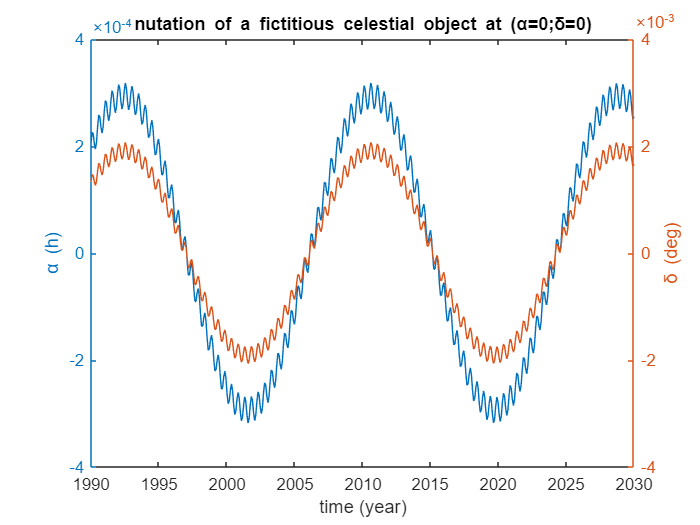

xaxis = linspace(1990,2030,492);
fig1 = plotyy(xaxis,alpha2,xaxis,delta2);
title('nutation of a fictitious celestial object at (\alpha=0;\delta=0)')
xlabel('time (year)')
ylabel(fig1(1),'\alpha (h)')
ylabel(fig1(2),'\delta (deg)')

**3.**

clc
clear

clc
clear
% vernaleqinox
alpha = 0; delta = 0;
vernaleqinox = [delta,alpha,1];
xi0 = latlonr2xyz(vernaleqinox);  %(rad,rad,m)-->(m,m,m)

[year,month,day,mjd,xpol,ypol,dUT1,LOD,dX,dY...
s_xpol,s_ypol,s_dUT1,s_LOD,s_dX,s_dy] = textread('IAU1980_body2021.txt');

% Xpol,Ypol between 2021-06-11 & 2021-06-12
%Row 162 - 2021-06-11
%Row 163 - 2021-06-12
xpol_inter = interp1(xpol(162:163),1:(1/24):2),...
ypol_inter = interp1(ypol(162:163),1:(1/24):2)

xpol_inter =     0.1742    0.1743    0.1743    0.1744    0.1744    0.1745    0.1745    0.1746    0.1747    0.1747    0.1748    0.1748    0.1749    0.1749    0.1750    0.1750    0.1751    0.1751    0.1752    0.1752    0.1753    0.1753    0.1754    0.1754    0.1755


ypol_inter =     0.4357    0.4357    0.4357    0.4357    0.4357    0.4357    0.4356    0.4356    0.4356    0.4356    0.4356    0.4356    0.4356    0.4355    0.4355    0.4355    0.4355    0.4355    0.4355    0.4355    0.4355    0.4354    0.4354    0.4354    0.4354


- Inter polation of Xp,Yp [sec. deg.] (hourly between 2021-06-11 & 2021-06-12)

%W(Xp,Yp)
for i = 1:length(xpol_inter)
    w = pol(xpol_inter(i),ypol_inter(i));
    xiw = w*xi0';
    % (m,m,m) --> (rad,rad,m) %
    % sph_iw = xyz2latlonr(xiw); 
    % [delta,alpha,1] - [rad,rad,m]
    disp(i);disp(w)
    % delta2(i) = sph_iw(1)*180/pi; % degree
    % alpha2(i) = sph_iw(2)*12/pi; % hour angle
end

     1

    1.0000    0.0000    0.0000
         0    1.0000   -0.0000
   -0.0000    0.0000    1.0000

     2

    1.0000    0.0000    0.0000
         0    1.0000   -0.0000
   -0.0000    0.0000    1.0000

     3

    1.0000    0.0000    0.0000
         0    1.0000   -0.0000
   -0.0000    0.0000    1.0000

     4

    1.0000    0.0000    0.0000
         0    1.0000   -0.0000
   -0.0000    0.0000    1.0000

     5

    1.0000    0.0000    0.0000
         0    1.0000   -0.0000
   -0.0000    0.0000    1.0000

     6

    1.0000    0.0000    0.0000
         0    1.0000   -0.0000
   -0.0000    0.0000    1.0000

     7

    1.0000    0.0000    0.0000
         0    1.0000   -0.0000
   -0.0000    0.0000    1.0000

     8

    1.0000    0.0000    0.0000
         0    1.0000   -0.0000
   -0.0000    0.0000    1.0000

     9

    1.0000    0.0000    0.0000
         0    1.0000   -0.0000
   -0.0000    0.0000    1.0000

    10

    1.0000    0.0000    0.0000
         0    1.0000   -0.0000
   -0.0000  

- Polar motion matrix W for a given time (hourly between 2021-06-11 & 2021-06-12)

%delta2;
%alpha2;

**4.**

clc
clear

%% ICRF3 catalog
%0454+844
a04 = [5*360/24 8 42.36351222]; % alpha - [deg min sec]
d04 = [84 32 04.5441733]; % delta - [deg min sec]
a04 = dms2dd(a04); d04 = dms2dd(d04); % Convert to [dec deg]
%1101−536
a1101 = [11*360/24 3 52.22168463]; 
d1101 = -1*[53 57 00.6966389];
a1101 = dms2dd(a1101); d1101 = dms2dd(d1101);
%1111+149 
a1111 = [11*360/24 13 58.69508613];
d1111 = [14 42 26.9526507];
a1111 = dms2dd(a1111); d1111 = dms2dd(d1111);
%1738+499
a17 = [17*360/24 39 27.39049431];
d17 = [49 55 03.3683385];
a17 = dms2dd(a17); d17 = dms2dd(d17);
%Spherical Coordinate of 4 Objects
obj1 = [d04,a04,1]; obj2 = [d1101,a1101,1];
obj3 = [d1111,a1111,1]; obj4 = [d17,a17,1];

%Cartesian Coordinate of 4 Objects
xi0_1 = latlonr2xyz(obj1),...
xi0_2 = latlonr2xyz(obj2),...
xi0_3 = latlonr2xyz(obj3),...
xi0_4 = latlonr2xyz(obj4),...

%Berlin

xi0_1 =    -0.9281    0.2401    0.2844


xi0_2 =     0.1117   -0.8488    0.5168


xi0_3 =     0.1592   -0.5159    0.8417


xi0_4 =    -0.3506   -0.8723   -0.3409


lat_berlin = [52 36 0];% deg min sec 
lon_berlin = [13 24 0];% deg min sec
lat_berlin = dms2dd(lat_berlin); lon_berlin = dms2dd(lon_berlin);
berlin = [lat_berlin,lon_berlin,1]

berlin =    52.6000   13.4000    1.0000



%polar motion
[year,month,day,mjd,xpol,ypol,dUT1,LOD,dX,dY...
s_xpol,s_ypol,s_dUT1,s_LOD,s_dX,s_dy] = textread('IAU1980_body2021.txt');

% Xpol,Ypol between 2021-06-11 & 2021-06-12 
%Row 162 - 2021-06-11
%Row 163 - 2021-06-12
xpol_inter = interp1(xpol(162:163),1:(1/24/60):2);%in min. resolution
ypol_inter = interp1(ypol(162:163),1:(1/24/60):2);%in min. resolution

% JD in 2021-06-11 & 12 with min. resolution
mm=6;yyyy = 2021;
dd=1; ut1=1:24; minute=1:60; second=0;
j = 1;
for ut1 = 1:24
    % Seperated Each Hour
    jd = gre2jd(yyyy,mm,dd,ut1,minute,second); 
    % JD of 1 min in Specific hr
    jd = jd(1:60); % Extract only Julian Date
    jd_all(j:j+59) = jd; %Insert Each Year of JD value in 1 hour
    j = j+60;
end
% The final time
lastmin = gre2jd(2021,6,12,0,0,0);
jd_all(1441) = lastmin(1);
jd_all;
% All JD in one day with min resolution


for i = 1:length(xpol_inter)

    t = (jd_all(i) - 2451545.0)/36525;
    GMST(i) = (F(jd_all(i))*86400 + 24110.54841 - 86400/2 + ...
        8640184.812866 * t + 0.093104 * t * t - ...
        6.2e-6 * t * t * t)/3600*60; % [min]
    GMST(i) = rem(GMST(i),60);

    w = pol(xpol_inter(i),ypol_inter(i));
    %Object 1
    xg_1 = ref3d(1)*rot3d(90-lat_berlin,2)*rot3d(lon_berlin,3)*...
    w*rot3d(GMST(i),3)*nut(jd_all(i))*prec(jd_all(i))*xi0_1';
    %sph_xg = xyz2latlonr(xg)
    A_1(i) = atan2(xg_1(2),xg_1(1)); %rad
    E_1(i) = atan(xg_1(3)/sqrt(xg_1(1)^2+xg_1(2)^2));%rad
    
    %Object 2
    xg_2 = ref3d(1)*rot3d(90-lat_berlin,2)*rot3d(lon_berlin,3)*...
    w*rot3d(GMST(i),3)*nut(jd_all(i))*prec(jd_all(i))*xi0_2';
    %sph_xg = xyz2latlonr(xg)
    A_2(i) = atan2(xg_2(2),xg_2(1)); %rad
    E_2(i) = atan(xg_2(3)/sqrt(xg_2(1)^2+xg_2(2)^2));%rad
    
    %Object 3
    xg_3 = ref3d(1)*rot3d(90-lat_berlin,2)*rot3d(lon_berlin,3)*...
    w*rot3d(GMST(i),3)*nut(jd_all(i))*prec(jd_all(i))*xi0_3';
    %sph_xg = xyz2latlonr(xg)
    A_3(i) = atan2(xg_3(2),xg_3(1)); %rad
    E_3(i) = atan(xg_3(3)/sqrt(xg_3(1)^2+xg_3(2)^2));%rad

    %Object 4
    xg_4 = ref3d(1)*rot3d(90-lat_berlin,2)*rot3d(lon_berlin,3)*...
    w*rot3d(GMST(i),3)*nut(jd_all(i))*prec(jd_all(i))*xi0_4';
    %sph_xg = xyz2latlonr(xg)
    A_4(i) = atan2(xg_4(2),xg_4(1)); %rad
    E_4(i) = atan(xg_4(3)/sqrt(xg_4(1)^2+xg_4(2)^2));%rad

end

A_1 = A_1*180/pi;
for m = 1:length(A_1)
    if A_1(m) < 0
        A_1(m) = A_1(m)+360;
    end
end%
A_1,...
E_1 = E_1*180/pi,...

A_2 = A_2*180/pi;

A_1 =    62.4816   63.2762   64.0683   64.8581   65.6455   66.4309   67.2142   67.9957   68.7755   69.5537   70.3304   71.1059   71.8802   72.6535   73.4259   74.1977   74.9689   75.7397   76.5104   77.2809   27.7375   28.6963   29.6506   30.6004   31.5457   32.4864   33.4224   34.3538   35.2805   36.2025   37.1197   38.0322   38.9400   39.8431   40.7415   41.6352   42.5242   43.4086   44.2883   45.1636   46.0343   46.9005   47.7624   48.6199   49.4732   50.3222   51.1671   52.0080   52.8448   53.6778


E_1 =     0.1372    0.6792    1.2251    1.7746    2.3277    2.8843    3.4441    4.0072    4.5735    5.1427    5.7148    6.2896    6.8672    7.4473    8.0298    8.6147    9.2018    9.7911   10.3823   10.9755  -16.9562  -16.6683  -16.3714  -16.0657  -15.7514  -15.4285  -15.0972  -14.7576  -14.4099  -14.0541  -13.6905  -13.3191  -12.9400  -12.5535  -12.1597  -11.7586  -11.3504  -10.9353  -10.5134  -10.0848   -9.6497   -9.2082   -8.7603   -8.3064   -7.8464   -7.3806   -6.9090   -6.4317   -5.9490   -5.4610


for n = 1:length(A_2)
    if A_2(n) < 0
        A_2(n) = A_2(n)+360;
    end
end%
A_2,...
E_2 = E_2*180/pi,...

A_3 = A_3*180/pi;

A_2 =   323.2336  324.0127  324.7947  325.5796  326.3675  327.1583  327.9520  328.7486  329.5481  330.3504  331.1556  331.9636  332.7744  333.5879  334.4042  335.2231  336.0446  336.8687  337.6954  338.5245  294.1515  294.8524  295.5536  296.2552  296.9573  297.6601  298.3636  299.0680  299.7734  300.4799  301.1876  301.8966  302.6069  303.3188  304.0322  304.7472  305.4640  306.1827  306.9032  307.6257  308.3503  309.0769  309.8058  310.5370  311.2704  312.0063  312.7446  313.4853  314.2286  314.9745


E_2 =     2.2243    1.8631    1.5086    1.1609    0.8201    0.4863    0.1595   -0.1600   -0.4724   -0.7773   -1.0749   -1.3649   -1.6474   -1.9222   -2.1892   -2.4484   -2.6996   -2.9429   -3.1781   -3.4052   21.0288   20.4746   19.9235   19.3757   18.8312   18.2900   17.7523   17.2182   16.6877   16.1609   15.6380   15.1189   14.6039   14.0929   13.5860   13.0834   12.5852   12.0914   11.6021   11.1174   10.6374   10.1622    9.6918    9.2264    8.7661    8.3110    7.8610    7.4165    6.9773    6.5437


for o = 1:length(A_3)
    if A_3(o) < 0
        A_3(o) = A_3(o)+360;
    end
end%
A_3,...
E_3 = E_3*180/pi,...

A_4 = A_4*180/pi;

A_3 =   330.3075  330.8189  331.3325  331.8482  332.3660  332.8858  333.4076  333.9315  334.4573  334.9850  335.5147  336.0462  336.5796  337.1148  337.6518  338.1906  338.7311  339.2733  339.8171  340.3626  311.8994  312.3090  312.7216  313.1372  313.5558  313.9773  314.4017  314.8290  315.2591  315.6920  316.1278  316.5663  317.0075  317.4515  317.8981  318.3474  318.7994  319.2540  319.7113  320.1711  320.6335  321.0984  321.5659  322.0358  322.5083  322.9833  323.4607  323.9405  324.4228  324.9074


E_3 =    28.4100   28.1106   27.8161   27.5263   27.2414   26.9614   26.6862   26.4161   26.1510   25.8909   25.6359   25.3861   25.1414   24.9020   24.6677   24.4388   24.2152   23.9970   23.7841   23.5767   43.6897   43.2378   42.7889   42.3430   41.9001   41.4603   41.0236   40.5900   40.1597   39.7326   39.3089   38.8885   38.4715   38.0579   37.6478   37.2412   36.8383   36.4389   36.0432   35.6513   35.2631   34.8787   34.4982   34.1215   33.7489   33.3802   33.0155   32.6550   32.2986   31.9463


for q = 1:length(A_4)
    if A_4(q) < 0
        A_4(q) = A_4(q)+360;
    end
end%
A_4,...
E_4 = E_4*180/pi,...
 
% Time plot obj 1

A_4 =   334.5997  336.2015  337.8208  339.4570  341.1090  342.7761  344.4571  346.1509  347.8563  349.5721  351.2969  353.0292  354.7677  356.5108  358.2571    0.0049    1.7527    3.4989    5.2420    6.9805  286.0141  286.9413  287.8786  288.8264  289.7850  290.7549  291.7365  292.7301  293.7363  294.7553  295.7878  296.8339  297.8943  298.9693  300.0594  301.1650  302.2866  303.4245  304.5793  305.7513  306.9409  308.1486  309.3746  310.6195  311.8836  313.1671  314.4704  315.7937  317.1373  318.5014


E_4 =   -55.3541  -55.6077  -55.8455  -56.0674  -56.2729  -56.4616  -56.6334  -56.7879  -56.9249  -57.0441  -57.1453  -57.2284  -57.2931  -57.3394  -57.3672  -57.3764  -57.3671  -57.3392  -57.2928  -57.2279  -36.7947  -37.3788  -37.9599  -38.5380  -39.1127  -39.6841  -40.2517  -40.8155  -41.3751  -41.9304  -42.4812  -43.0271  -43.5680  -44.1036  -44.6336  -45.1577  -45.6758  -46.1874  -46.6923  -47.1902  -47.6807  -48.1636  -48.6385  -49.1051  -49.5630  -50.0118  -50.4513  -50.8809  -51.3004  -51.7094


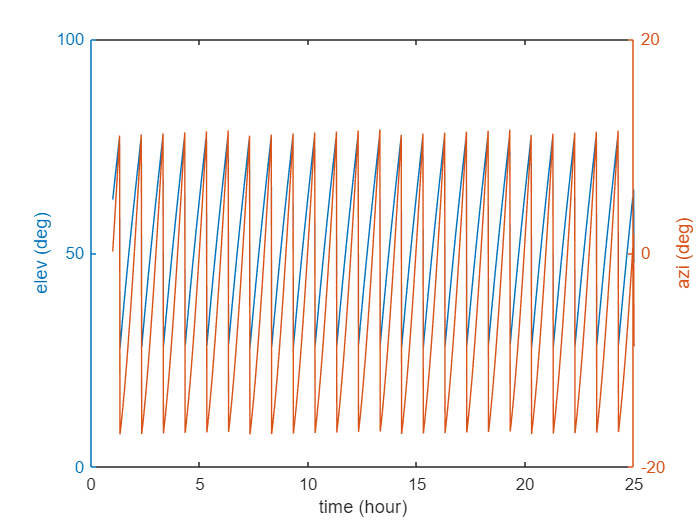

figure(1)
xaxis = linspace(1,25,1441);
fig1 = plotyy(xaxis,A_1,xaxis,E_1);
xlabel('time (hour)')
ylabel(fig1(1),'elev (deg)')
ylabel(fig1(2),'azi (deg)')

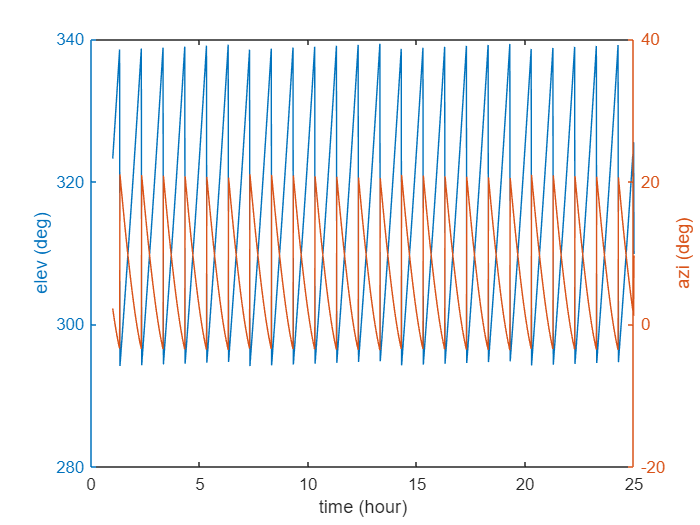



% Time plot obj 2
figure(2)
fig2 = plotyy(xaxis,A_2,xaxis,E_2);
xlabel('time (hour)')
ylabel(fig2(1),'elev (deg)')
ylabel(fig2(2),'azi (deg)')

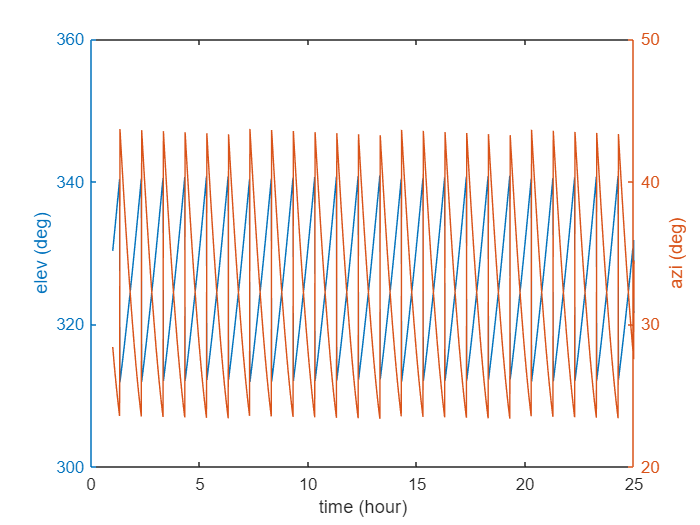



% Time plot obj 3
figure(3)
fig3 = plotyy(xaxis,A_3,xaxis,E_3);
xlabel('time (hour)')
ylabel(fig3(1),'elev (deg)')
ylabel(fig3(2),'azi (deg)')

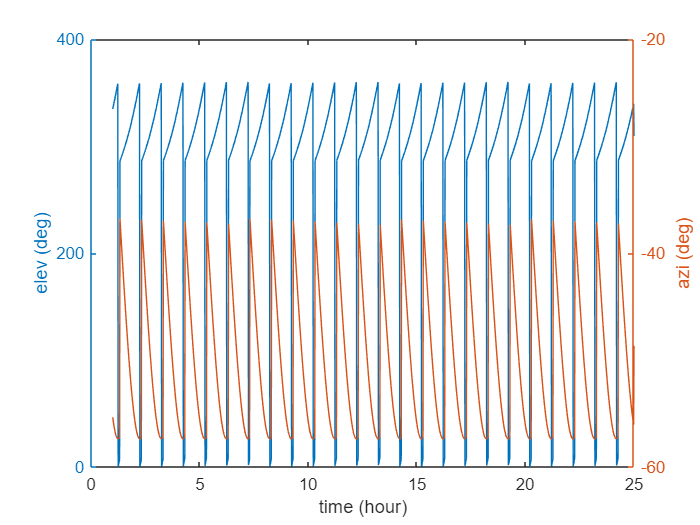



% Time plot obj 4
figure(4)
fig4 = plotyy(xaxis,A_4,xaxis,E_4);
xlabel('time (hour)')
ylabel(fig4(1),'elev (deg)')
ylabel(fig4(2),'azi (deg)')

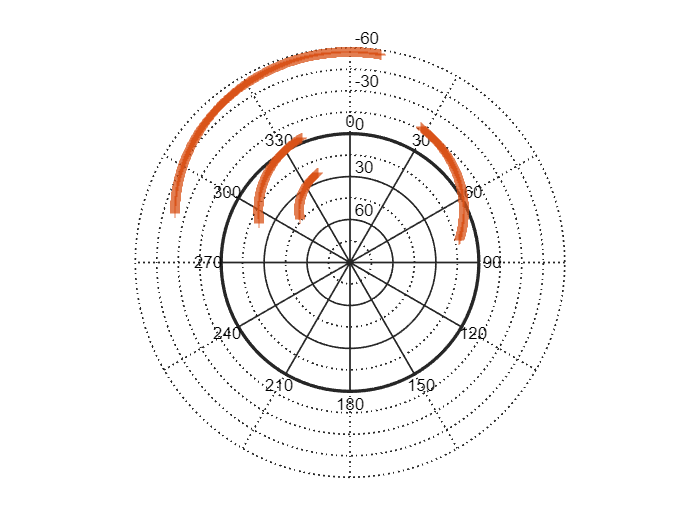

%Sky plot of 4 objs
figure(5)
all_azi = [A_1 A_2 A_3 A_4];
all_elev = [E_1 E_2 E_3 E_4];
skyplot(all_azi,all_elev,'+')

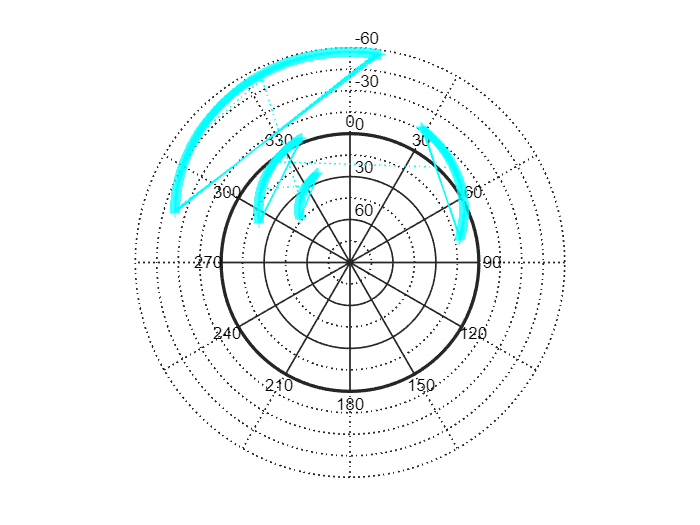

figure(6)
skyplot(all_azi,all_elev,'c+:') % Changed Style